L = 11*1.1/10

L = 1.2100

D = 3; l = 8; 
W = sqrt(L*(l/D+0.44)/(0.01*D))

W = 11.1938

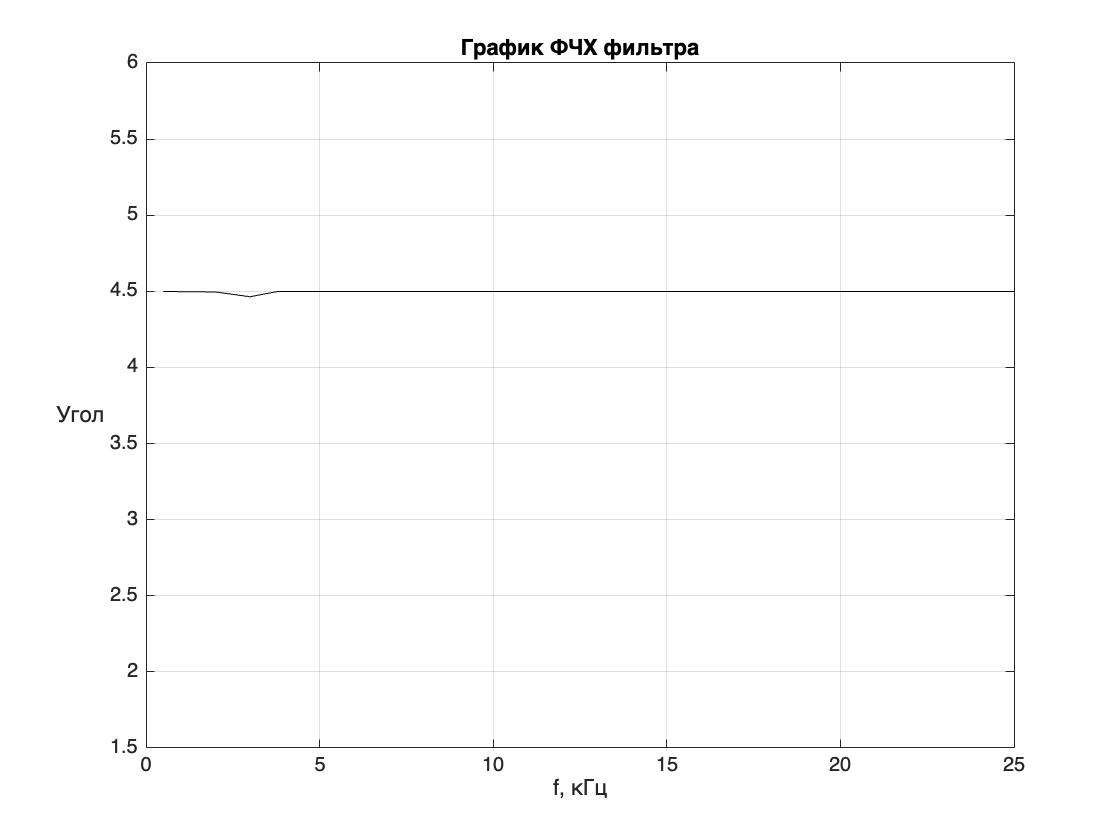

f =     [1,    2,     5,     10,    15,   16,  17,  20, 25];
U_in = 707;                                           
U_out = [4.9, 5,  25.3, 120.4, 480,  52.3, 29.3, 13.2, 7.2];
K_p2 = U_out./U_in;
% Kp = [10, 13.5, 41.2, 70.4, 202.2, 24.4, 6.2, 4, 3.7, 3.4, 2.8, 2.4]*1e-3;
phi =   [89.99, 89.80, 89.65, 86.87, 89.99, 89.99, 89.98, 89.98, 89.96, 89.95, 89.97, 89.97, 89.98, 89.99, 89.98];
f2 = [0.5, 1, 2, 3, 3.8, 3.9, 3.97, 4.07, 5, 10, 15, 16, 17, 20, 25];
my_plot(f, log(K_p2), "График АЧХ фильтра", "f, МГц", "К_п")
my_plot(f2, log(phi), "График ФЧХ фильтра", "f, кГц", "Угол")
ylim([1.5, 6])

function my_plot(x, y, title_txt, xlabel_txt, ylabel_txt)
    plot(x, y, "Color", "black");
    grid on
    title(title_txt)
    xlabel(xlabel_txt)
    ylabel(ylabel_txt, Rotation=0, HorizontalAlignment='right', VerticalAlignment='top')
    saveas(gcf, title_txt, 'png')
end